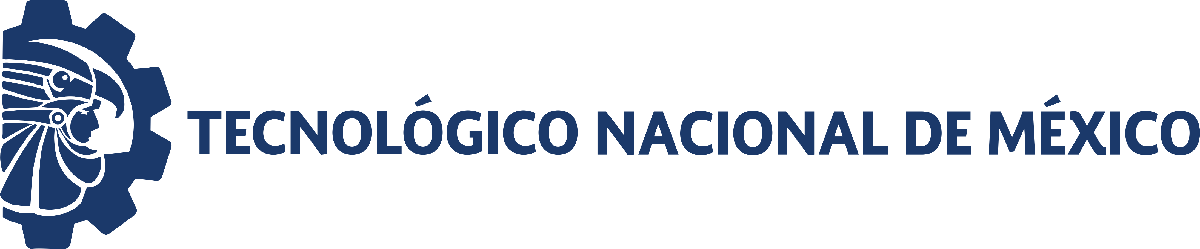                                 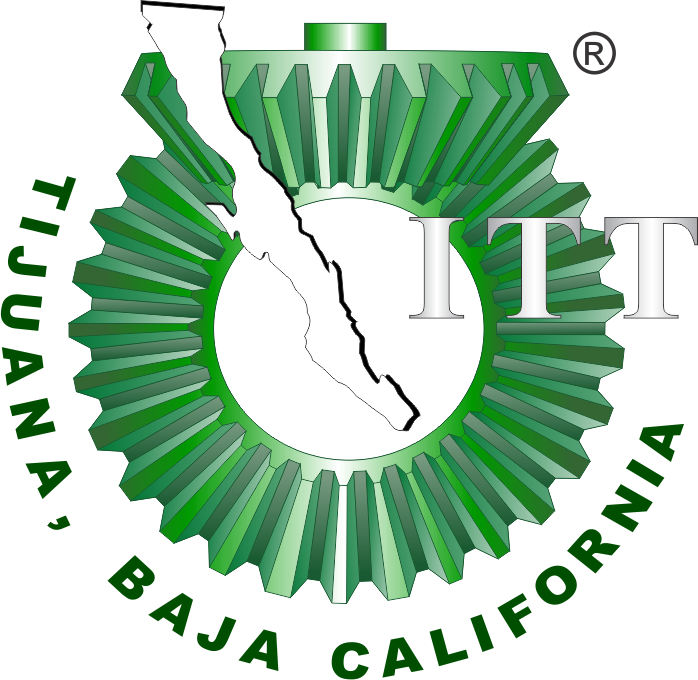

# Práctica 3: Algoritmos de regresión no lineal

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

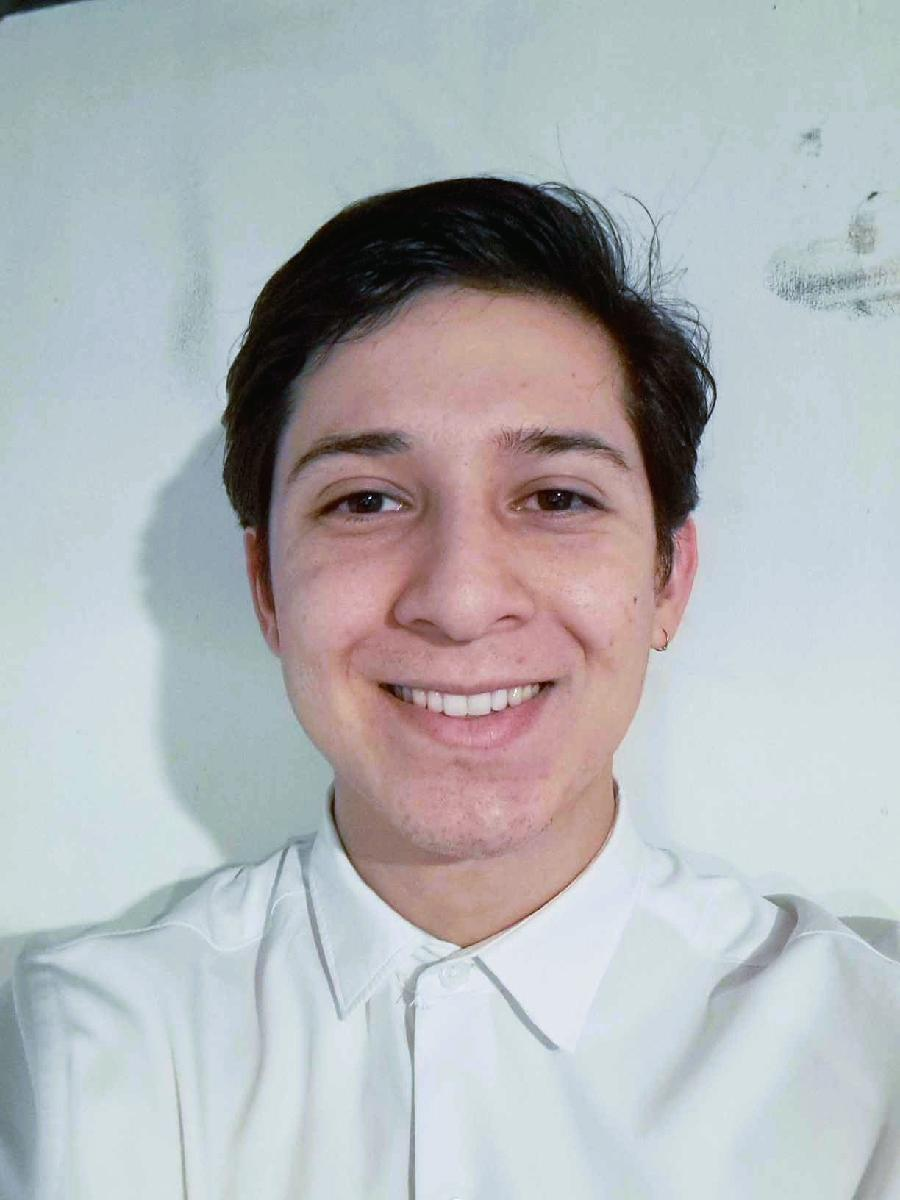

Nombre del alumno: **Jesus Zamora Cervantes**

Número de control: **21212185**

Correo institucional: **l21212185@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation data

    Time    x1: Sample 1    x2: Sample 2     xo: Mean 
    ____    ____________    ____________    __________

      0      6.7923e+07      6.7772e+07     6.7847e+07
      8      1.3379e+08       1.027e+08     1.1825e+08
     16      4.3319e+08      3.3628e+08     3.8474e+08
     24      8.9155e+08      8.6832e+08     8.7993e+08
     32      9.5773e+08      9.8052e+08     9.6912e+08
     40      9.8148e+08      9.9791e+08     9.8969e+08
     48      9.9525e+08      9.9276e+08       9.94e+08
     56      9.8971e+08           1e+09     9.9485e+08
     64           1e+09      9.7521e+08      9.876e+08
     72      9.9383e+08      9.7827e+08     9.8605e+08



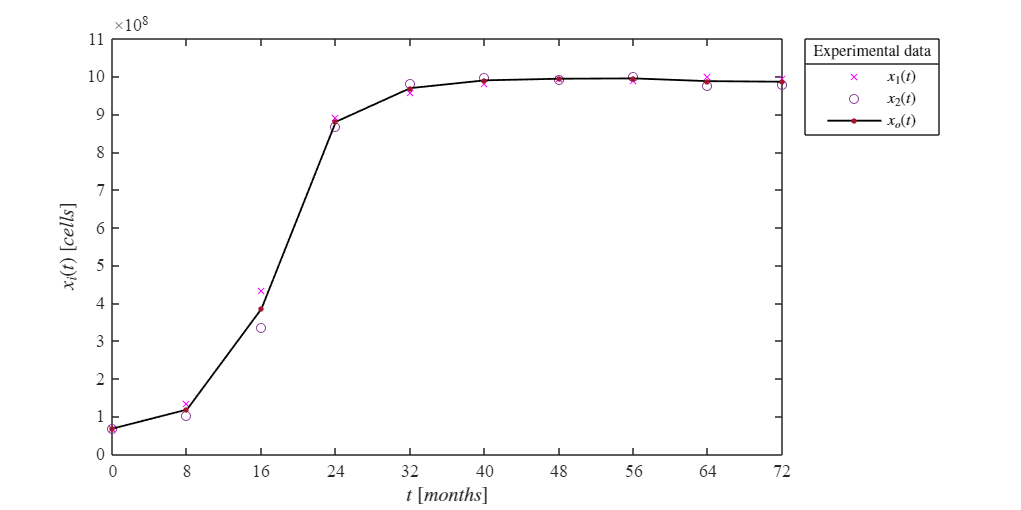

clc; clear; close all; warning('off','all')
sys = readmatrix('data .csv');
to = sys(:,1);
x1o = sys(:,2);
x2o = sys(:,3);
xo = mean([x1o,x2o],2);
T = array2table([to,x1o,x2o,xo],'VariableNames',{'Time','x1: Sample 1','x2: Sample 2','xo: Mean'});
disp(T);plotdata(to,x1o,x2o,xo);

xmax = max(xo);

### Nonlinear regression: Logistic law


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.9757
Corrected AIC (n/pars < 40): 388.1464

    Parameters    Estimate       SE          MoE             CI95             pvalue  
    __________    ________    _________    ________    _________________    __________

       "k"        0.16158     0.0095842    0.021681    0.1399    0.18327    4.0727e-08



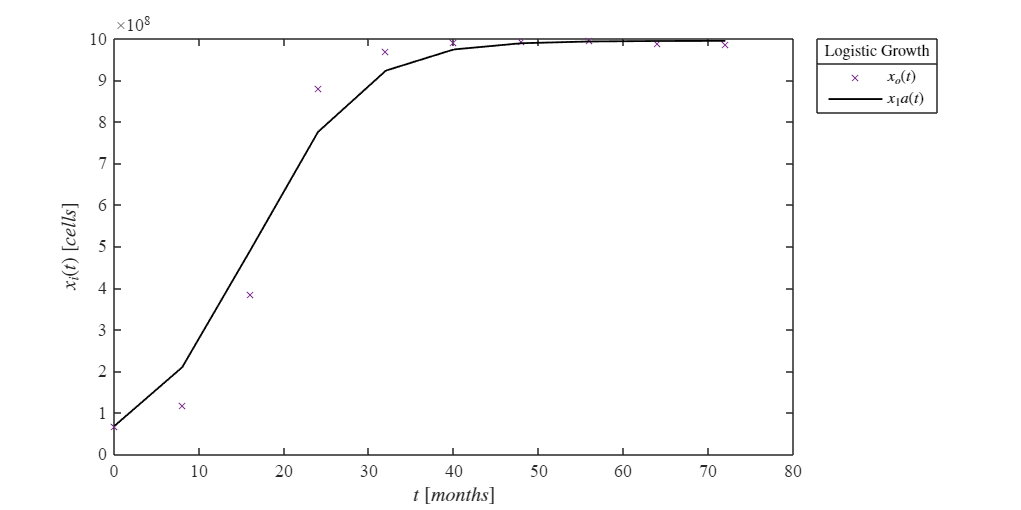

b = 1/xmax;
k0 = 1E-3; %Valor inicial%
mdl_logistic = logistic(to,xo,k0,b); x1a = mdl_logistic.Fitted; plotfit(to,xo,x1a);

## Nonlinear regression: Alometric growth law (sphere)


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.92352
Corrected AIC (n/pars < 40): 399.6135

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         56.982     7.4297    16.807    40.175    73.789    3.0955e-05



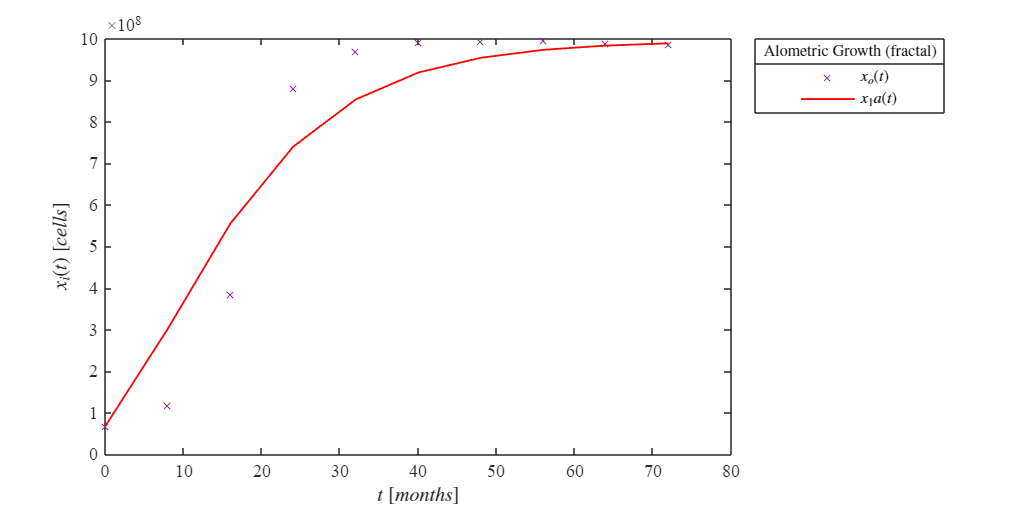

xmax = max(xo);
b1 = nthroot(1/xmax,4);
k0 = 1E-3; %Valor inicial%
mdl_sphere = sphere(to,xo,k0,b1); x3a = mdl_sphere.Fitted; plotfit2(to,xo,x3a);

## Nonlinear regression: Alometric growth law(fractal)


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.91801
Corrected AIC (n/pars < 40): 400.3094

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         228.81     31.385    70.999    157.82    299.81    4.6116e-05



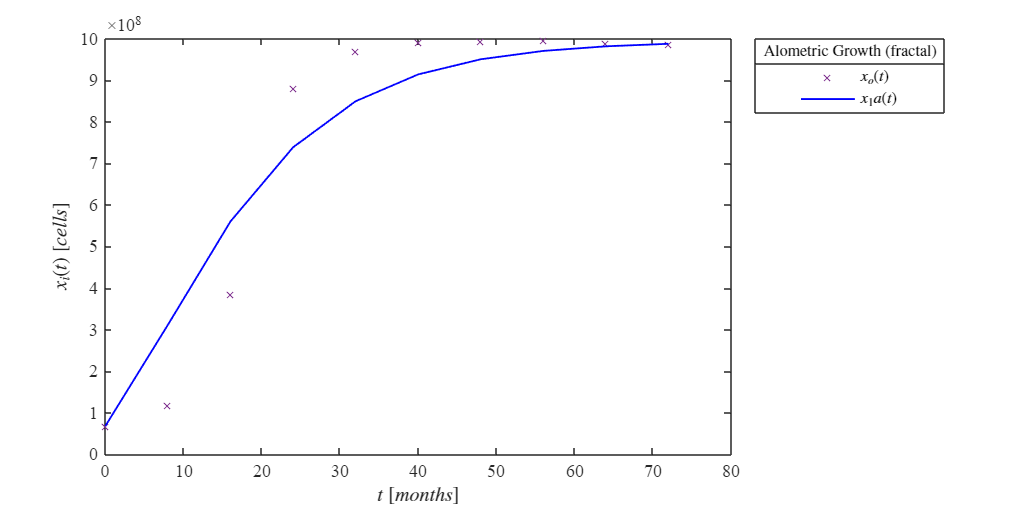

xmax = max(xo);
b1 = nthroot(1/xmax,3);
k0 = 1E-3; %Valor inicial%
mdl_alometric = alometric(to,xo,k0,b1); x2a = mdl_alometric.Fitted; plotfit1(to,xo,x2a);

## Nonlinear regression: Gompertz growth law 


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate      SE         MoE            CI95            pvalue  
    __________    ________    _______    _______    ________________    __________

       "k"         1.9245     0.21469    0.48566    1.4389    2.4102    8.8198e-06



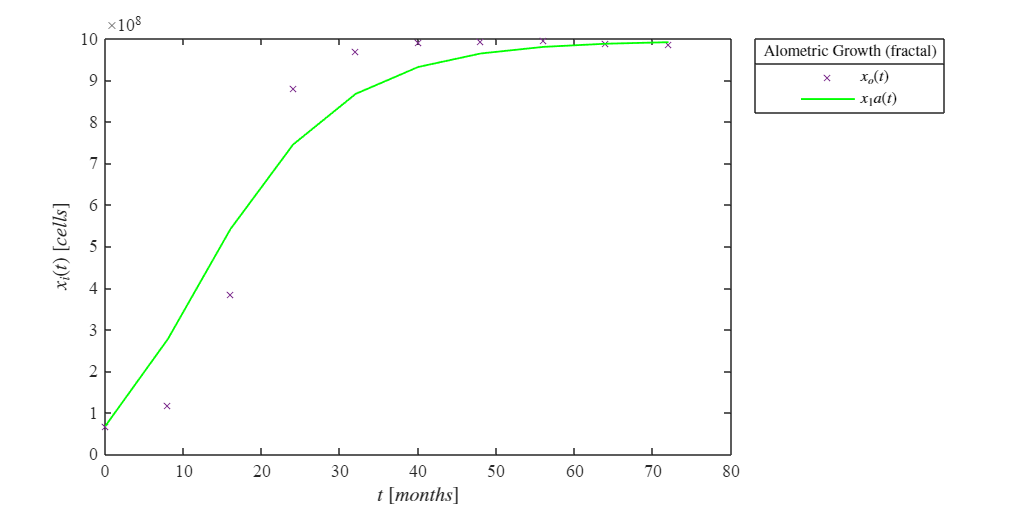

xmax = max(xo);
b1 = 1/log(xmax);
k0 = 1E-3; %Valor inicial%
mdl_gomperz = gomperz(to,xo,k0,b1); x4a = mdl_gomperz.Fitted; plotfit3(to,xo,x4a);

## Nonlinear regression: Gompertz growth law (simplified)


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate       SE         MoE              CI95             pvalue  
    __________    ________    ________    ________    __________________    __________

       "k"        0.092892    0.010362    0.023441    0.06945    0.11633    8.8203e-06



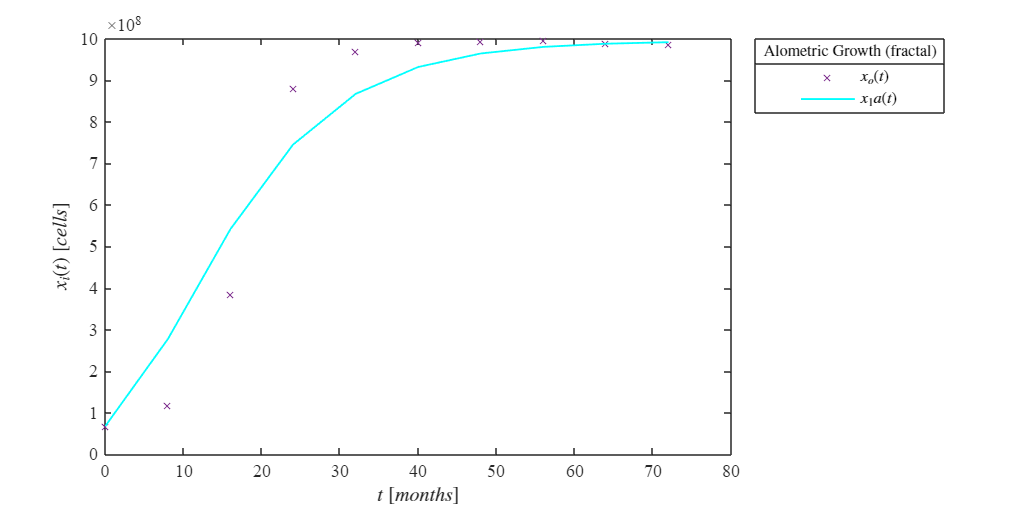

xmax = max(xo);
b1 = xmax;
k0 = 1E-3; %Valor inicial%
mdl_gomperzS = gomperzS(to,xo,k0,b1); x5a = mdl_gomperzS.Fitted; plotfit4(to,xo,x5a);

## Functions

### Plotfit and observed data

function plotdata(to, x1o, x2o, xo)
    figure(1);
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];


    hold on; box on;
    plot(to, x1o, 'x', 'MarkerSize', 5, 'Color', 'm');
    plot(to, x2o, 'o', 'MarkerSize', 5, 'Color', pr);
    plot(to, xo, '-o', 'LineWidth', 1, 'MarkerSize', 2, 'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'k');
    hold off;

    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_1(t)$', '$x_2(t)$', '$x_o(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Experimental data');
    xlim([0 72]); xticks(0:8:72);
    ylim([0 11E8]); yticks(0:1E8:11E8);

end

function plotfit(to, xo, x1a)
    figure(2)
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];

    hold on; box on;
    plot(to, xo,  'x', 'MarkerSize', 5, 'Color', pr); 
    plot(to, x1a, '-', 'LineWidth', 1, 'MarkerSize', 4, ...
         'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'k');
    hold off;
    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_o(t)$', '$x_1a(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Logistic Growth');
end

function plotfit1(to, xo, x2a)
    figure(3)
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];

    hold on; box on;
    plot(to, xo,  'x', 'MarkerSize', 5, 'Color', pr); 
    plot(to, x2a, '-', 'LineWidth', 1, 'MarkerSize', 4, ...
         'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'b');
    hold off;
    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_o(t)$', '$x_1a(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Alometric Growth (fractal)');
end
function plotfit2(to, xo, x3a)
    figure(4)
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];

    hold on; box on;
    plot(to, xo,  'x', 'MarkerSize', 5, 'Color', pr); 
    plot(to, x3a, '-', 'LineWidth', 1, 'MarkerSize', 4, ...
         'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'r');
    hold off;
    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_o(t)$', '$x_1a(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Alometric Growth (fractal)');
end

function plotfit3(to, xo, x4a)
    figure(5)
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];

    hold on; box on;
    plot(to, xo,  'x', 'MarkerSize', 5, 'Color', pr); 
    plot(to, x4a, '-', 'LineWidth', 1, 'MarkerSize', 4, ...
         'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'g');
    hold off;
    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_o(t)$', '$x_1a(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Alometric Growth (fractal)');
end

function plotfit4(to, xo, x5a)
    figure(6)
    set(gcf, 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);

    or = [0.8500 0.3250 0.0980]; 
    pr = [0.4940 0.1840 0.5560]; 
    gr = [0.4660 0.6740 0.1880]; 
    rd = [0.6350 0.0780 0.1840];

    hold on; box on;
    plot(to, xo,  'x', 'MarkerSize', 5, 'Color', pr); 
    plot(to, x5a, '-', 'LineWidth', 1, 'MarkerSize', 4, ...
         'MarkerFaceColor', rd, 'MarkerEdgeColor', rd, 'Color', 'c');
    hold off;
    xlabel('$t$ $[months]$', 'Interpreter', 'latex');
    ylabel('$x_i(t)$ $[cells]$', 'Interpreter', 'latex');
    L = legend({'$x_o(t)$', '$x_1a(t)$'}, 'Interpreter', 'latex', 'Location', 'NorthEastOutside');
    title(L, 'Alometric Growth (fractal)');
end

### Nonlinear regression algorithm: Logistic growth law

function mdl = logistic(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k*x*(1 - b*x);
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end


### Nonlinear regression algorithm: Alometric growth law (sphere)

function mdl = sphere(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k * x^(3/4) * (1 - b * x^(1/4));
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end

### Nonlinear regression algorithm: Alometric growth law

function mdl = alometric(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k * x^(2/3) * (1 - b * x^(1/3));
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end

### Nonlinear regression algorithm: Gompertz growth law

function mdl = gomperz(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k * x * (1 - b * log (x));
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end


### Nonlinear regression algorithm: Gompertz growth law (Simplified)

function mdl = gomperzS(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k * x * log ((b)/(x));
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end